# Trabajo práctico: Estimación de estados

clear;

## 1) Cálculo de la ganancia del observador (L).

El siguiente sistema mecánico está descripto por el siguiente modelo en espacio de estados,

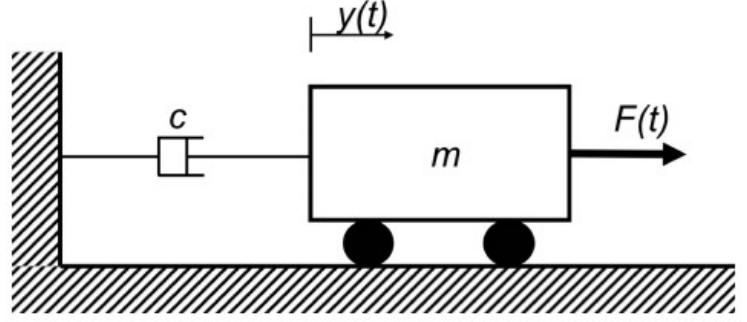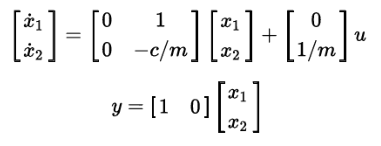

donde $m = 1$ y $c=1$ y $x_{1}$ es la posición de la masa, $x_{2}$ es la velocidad de la masa, $u$ es la fuerza e $y$ es la posición.

m = 1; c = 1;
A = [
    0   1;
    0   -c/m];
B = [0; 1/m];
C = [1  0];

#### a) Determine si el sistema es controlable.

Wr = [B A*B];
disp(rank(Wr));

     2



Dado que el rango es igual a n, el sisteba es **controlable**.

#### b) Si es controlable, calcule los valores de la matriz K y de kr para $p_{des}(s) = (s + 4)^{2}$

syms s;
I = eye(2);
K = sym('k', [1, 2]);
disp(K);

$$\left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

pol1 = det(s*I - (A - B*K));
pol2 = expand((s + 4)^2);
disp(pol1); disp(pol2);

$$k_{1}+s+k_{2}\,s+s^{2}$$

$$s^{2}+8\,s+16$$

c1 = fliplr(coeffs(pol1, s));
c2 = fliplr(coeffs(pol2, s));
disp(c1); disp(c2);

$$\left(\begin{array}{ccc} 1 & k_{2}+1 & k_{1} \end{array}\right)$$

$$\left(\begin{array}{ccc} 1 & 8 & 16 \end{array}\right)$$

K(1) = solve(c1(3) == c2(3));
K(2) = solve(c1(2) == c2(2));
disp(K);

$$\left(\begin{array}{cc} 16 & 7 \end{array}\right)$$

Verificación de la ubicación de los polos del sistema realimentado.

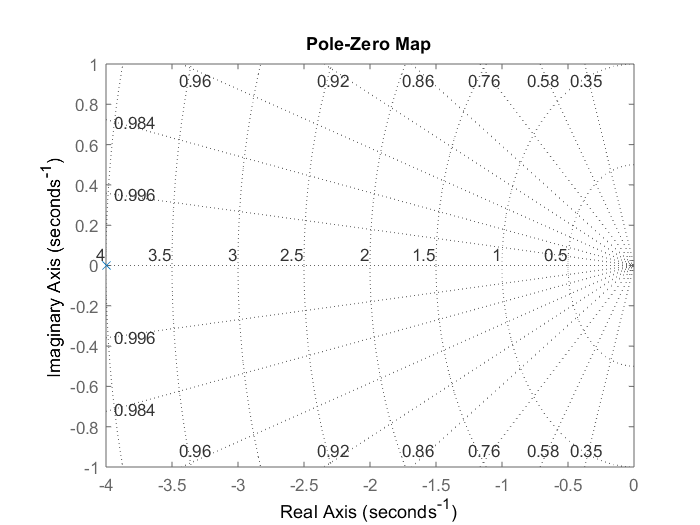

k1 = K(1); k2 = K(2);
H = tf(1, eval(subs(c1)));
pzmap(H);
grid on;

K = sym('k', [1, 2]);
kr = -inv(C*inv(A - B*K)*B);
disp(kr);

$$k_{1}$$

#### c) Determine si el sistema es observable.

Wo = [C; C*A];
disp(rank(Wo));

     2



Dado que el rango es igual a n, el sistema es **observable**.

#### d) Verifique si el sistema es observable para $C = [0\quad1]$ ¿Qué conslusión puede sacar?

Cv = [0  1];
Wo = [Cv; Cv*A];
disp(rank(Wo));

     1



El rango es menor a n, por lo que el sistema **no es observable **para la C planteada. Siendo $y(t) = C \cdot x(t)$, para la C planteada la salida en lugar de ser la posición de la masa es la velocidad de la masa. Por lo tanto, podemos afirmar que el sistema es **observable desde la posición de la masa pero no observable desde su velocidad**.

#### e) Si el sistema es observable con alguno de los sensores analizados, determine la ganancia del observador $L = [l_{1}\quad l_{2}]^{T}$ para el polinomio característico deseado $p_{des}(s) = (s + p)^{2}$. El principio de diseño (rule of thumb) indica que los polos del observador deben ser entre 4 y 5 veces más rápidos que los polos del sistema realimentado ¿Dónde ubicaría los polos del observador según esta regla?

L = sym('l', [2, 1]);
disp(L);

$$\left(\begin{array}{c} l_{1}\\ l_{2} \end{array}\right)$$

Los polos del observador deberían ubicarse siguiendo el polinomio $p_{des}(s) = (s + 20)^2$.

pol1 = det(s*I - (A - L*C));
pol2 = expand((s + 20)^2);
disp(pol1); disp(pol2);

$$l_{1}+l_{2}+s+l_{1}\,s+s^{2}$$

$$s^{2}+40\,s+400$$

c1 = fliplr(coeffs(pol1, s));
c2 = fliplr(coeffs(pol2, s));
disp(c1); disp(c2);

$$\left(\begin{array}{ccc} 1 & l_{1}+1 & l_{1}+l_{2} \end{array}\right)$$

$$\left(\begin{array}{ccc} 1 & 40 & 400 \end{array}\right)$$

L(1) = solve(c1(2) == c2(2));
L(2) = solve(c1(3) == c2(3), L(2));
disp(L);

$$\left(\begin{array}{c} 39\\ 400-l_{1} \end{array}\right)$$

Verificación de la ubicación de los polos del sistema realimentado.

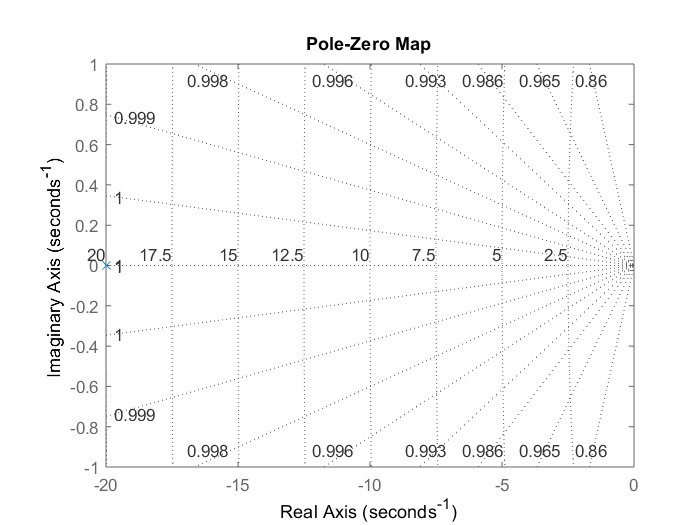

l1 = L(1); l2 = eval(L(2));
H = tf(1, eval(subs(c1)));
pzmap(H);
grid on;